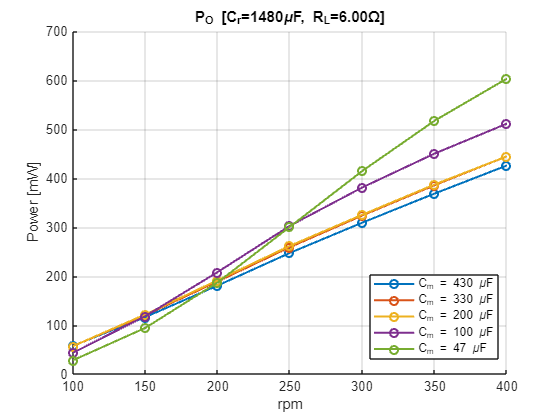


% Dati misurati con i tre bridge NVC gia' collegati in parallelo (NVC_1+2+3_f_sweep.csv):
% sweep di rpm per 5 valori fissi del condensatore di compensazione C_m, R_L = 6 Ohm
% fisso (valore reale di questa misura in parallelo, diverso dai carichi dei bridge singoli
% usati nel calcolo per bridge separato di C_sweep.mlx/R_sweep.mlx).
% CORREZIONI (valori anomali di un ordine di grandezza rispetto alle celle vicine della
% stessa riga/colonna, stesso tipo di errore di virgola gia' visto negli altri file):
%   rpm=100, C_m=200uF : Po  56.887  -> 568.87
%   rpm=150, C_m=47uF  : Pi 166.068  -> 1660.68
%   rpm=200, C_m=330uF : Pi 295.1    -> 2951.0
%   rpm=250, C_m=47uF  : Pi 487.07   -> 4870.7
%   rpm=300, C_m=430uF : Po 308.963  -> 3089.63
%   rpm=300, C_m=200uF : Pi 481.765  -> 4817.65
%   rpm=350, C_m=430uF : Po 368.306  -> 3683.06 , Pi 532.056 -> 5320.56
%   rpm=350, C_m=200uF : Pi 563.969  -> 5639.69
%   rpm=400, C_m=200uF : Pi 639.554  -> 6395.54
%
% PEE: vedi sezione piu' in basso ("Sweep di frequenza dei singoli bridge") -
% va confrontata con la somma dei bridge misurati singolarmente, non con la
% misura in parallelo di questa sezione (vedi nota li' per il motivo).

C_r = 1480e-6;      % F - condensatore di filtro/raddrizzatore, fisso
R_L = 6;            % Ohm - carico fisso durante la misura in parallelo

rpm_plot = [100 150 200 250 300 350 400];
C_L_plot = [430 330 200 100 47]*1e-6;   % F
n_CL = numel(C_L_plot);
colors = lines(n_CL);

% Potenza totale misurata con i tre bridge in parallelo, colonne = C_L_plot, righe = rpm_plot
P_real_tot_mW = [ ...
     577.051  568.574  568.870  433.322  280.937; ...
    1161.486 1201.984 1216.074 1181.846  940.781; ...
    1806.061 1889.706 1914.886 2081.096 1870.064; ...
    2472.505 2589.969 2616.579 3026.508 3005.614; ...
    3089.630 3234.652 3250.549 3807.637 4144.403; ...
    3683.060 3853.597 3868.507 4499.171 5170.465; ...
    4256.729 4442.665 4443.649 5110.765 6030.358];
P_real_tot = P_real_tot_mW/1000;

% Potenza in ingresso misurata (stessa disposizione), usata per l'efficienza sotto
P_in_tot_mW = [ ...
    1015.897 1017.819 1022.037  832.533  609.633; ...
    1876.022 1967.897 1993.338 2004.074 1660.680; ...
    2787.135 2951.000 2994.558 3364.592 3131.519; ...
    3705.191 3921.139 3966.523 4720.855 4870.700; ...
    4530.076 4786.681 4817.650 5788.334 6519.585; ...
    5320.560 5613.207 5639.690 6709.435 7930.267; ...
    6074.506 6387.661 6395.540 7518.051 9091.755];

% Rendimento di raddrizzamento eta_rec = P_O/P_I, calcolato dai dati reali sopra
eta_in = P_real_tot_mW ./ P_in_tot_mW;


figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, P_real_tot(:,k)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('Power [mW]');

legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');

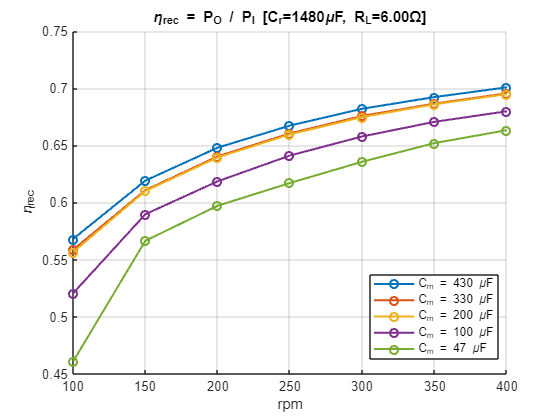

hold off;


%%%efficiency
figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, eta_in(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('\\eta_{rec} = P_{O} / P_{I} [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('\eta_{rec}');

legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;



% Sweep di frequenza dei singoli bridge NVC1/NVC2/NVC3 (NVC1_f sweep.csv, NVC2 _f_sweep.csv,
% NVC3_f_sweep.csv), un grafico ciascuno, a confronto con la misura in parallelo sopra.
% R_L e' il carico fisso di ciascun bridge preso singolarmente (diverso da R_L=6 Ohm
% della misura in parallelo sopra).
% NOTA: NVC3, C_m=330uF, rpm=400: Pi=260.307 mW e' anomalo (vedi nota nella versione
% precedente di questo file) ma non e' usato qui, che riporta solo Po.

R_L_b1 = 24;   % Ohm
R_L_b2 = 21;   % Ohm
R_L_b3 = 21;   % Ohm

P_b1_mW = [ ...
     22.5441  22.4484  22.2370  15.0196   6.7455; ...
     47.0499  46.8711  47.3067  44.9907  30.3036; ...
     72.9878  72.8348  73.8053  80.8427  71.0311; ...
     97.3926  97.0536  98.6034 131.9811 119.0619; ...
    123.0420 122.7463 124.4797 147.6066 170.0987; ...
    148.4621 148.0113 150.1617 181.2953 226.1011; ...
    177.2804 177.2099 180.4061 221.3496 287.8479];

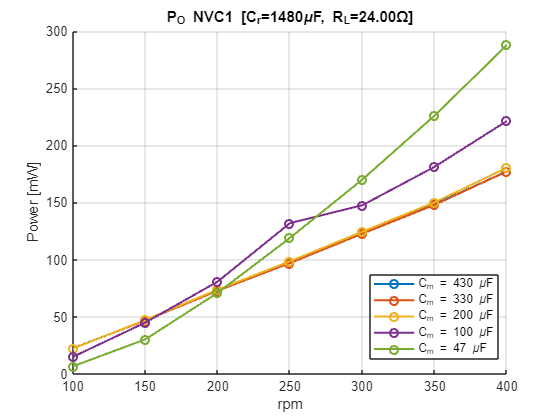


P_b2_mW = [ ...
     20.7543  20.0398  20.0184  12.6790   6.3577; ...
     41.6973  43.8949  44.2315  41.0067  29.0927; ...
     64.1064  68.4160  68.9850  76.2403  67.1217; ...
     86.4971  92.2757  92.8187 110.2216 112.8008; ...
    106.1984 112.3881 113.1919 136.8683 153.6134; ...
    124.0439 131.2896 132.0791 159.2458 186.0821; ...
    141.4300 148.9768 149.6349 178.0733 210.5053];

P_b3_mW = [ ...
     18.4568  18.1678  18.2953  11.9299   6.7836; ...
     35.9005  36.7541  37.0688  37.2239  28.1674; ...
     55.6874  57.0963  57.5861  67.8566  63.5425; ...
     76.6463  78.5914  79.0661  98.5006  87.9643; ...
     96.5324  98.6903  99.1909 125.5984 110.2023; ...
    116.1354 118.5912 119.0624 150.7551 131.6774; ...
    134.4762 137.2840 137.7494 174.0370 151.7686];

P_real_b1_f = P_b1_mW/1000;
P_real_b2_f = P_b2_mW/1000;
P_real_b3_f = P_b3_mW/1000;

figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, P_real_b1_f(:,k)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O NVC1 [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L_b1));
xlabel('rpm');
ylabel('Power [mW]');
legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;

figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, P_real_b2_f(:,k)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O NVC2 [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L_b2));
xlabel('rpm');
ylabel('Power [mW]');
legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;

figure;
hold on;
for k = 1:n_CL

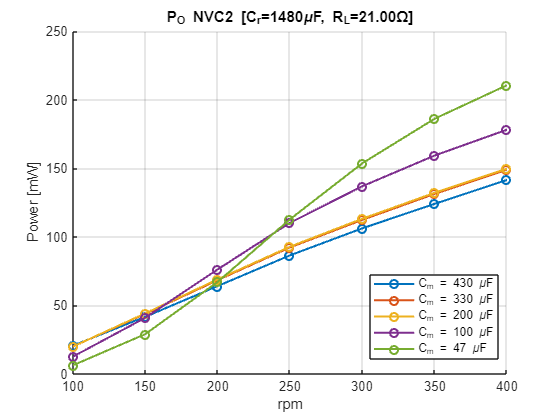

    plot(rpm_plot, P_real_b3_f(:,k)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O NVC3 [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L_b3));
xlabel('rpm');
ylabel('Power [mW]');
legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;


% PEE (Power Extraction Efficiency = P_real / P_matched)
% P_matched(rpm) viene dallo sweep di R_L sul circuito ideale (solo R_coil + NVC,

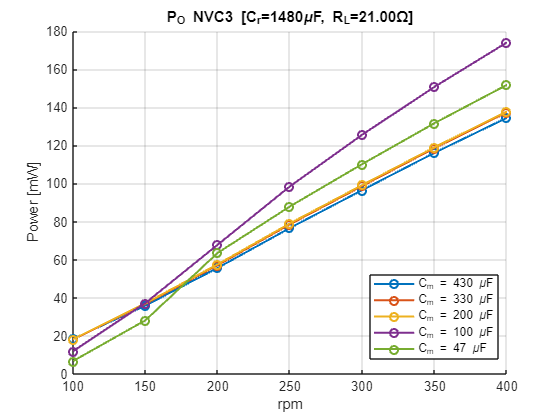

% niente L ne' C_m/C_r) in Best_R_L.mlx (cartella Internship/.../Sweep RL ideal):
% per ogni rpm e' la potenza di picco trovata variando R_L, sommata sui tre bridge.
% Va confrontata con la SOMMA dei tre bridge misurati singolarmente (P_b1+P_b2+P_b3
% sopra), non con la misura reale in parallelo di inizio file: quest'ultima e' una
% misura a R_L=6 Ohm CONDIVISO tra i tre bridge collegati insieme (tre sorgenti in
% parallelo su un solo carico), mentre Best_R_L.mlx simula tre circuiti INDIPENDENTI
% ciascuno con il proprio carico ottimo — due configurazioni elettriche diverse.
% Usando la misura in parallelo si otteneva PEE = 4-9, chiaramente non fisico;
% con la somma dei bridge singoli PEE resta correttamente <= 1.

% P_matched_mW = [64.824, 145.994, 265.274, 409.034, 571.354, 752.990, 958.267].';  % rpm = 100:50:400
% 
% P_real_indiv_sum_mW = P_b1_mW + P_b2_mW + P_b3_mW;
% Pee = P_real_indiv_sum_mW ./ P_matched_mW;
% 
% figure;

% hold on;
% for k = 1:n_CL
%     plot(rpm_plot, Pee(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
% end
% grid on;
% title(sprintf('PEE = P_{Real} / P_{Matched} [C_r=%.0f\\muF]', C_r*1e6));
% xlabel('rpm');
% ylabel('PEE');
% 
% legendEntries = cell(1, n_CL);
% for k = 1:n_CL
%     legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
% end
% legend(legendEntries, 'Location', 'best');
% hold off;
